clf
numg = 1;
deng = poly([0 -4 -6])

deng =      1    10    24     0


G = tf(numg,deng)

G =
 
           1
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.



pos = input('Type desired %OS');
z = -log(pos/100)/sqrt(pi^2+(log(pos/100))^2)

z = 0.5039

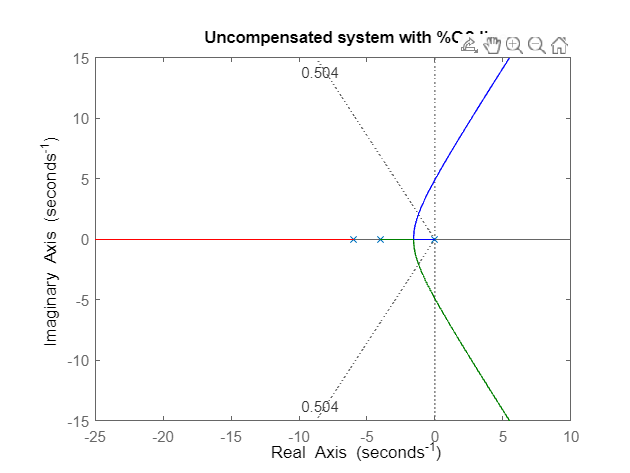

rlocus(G)
sgrid(z,0)
title('Uncompensated system with %OS line');

Select a point in the graphics window


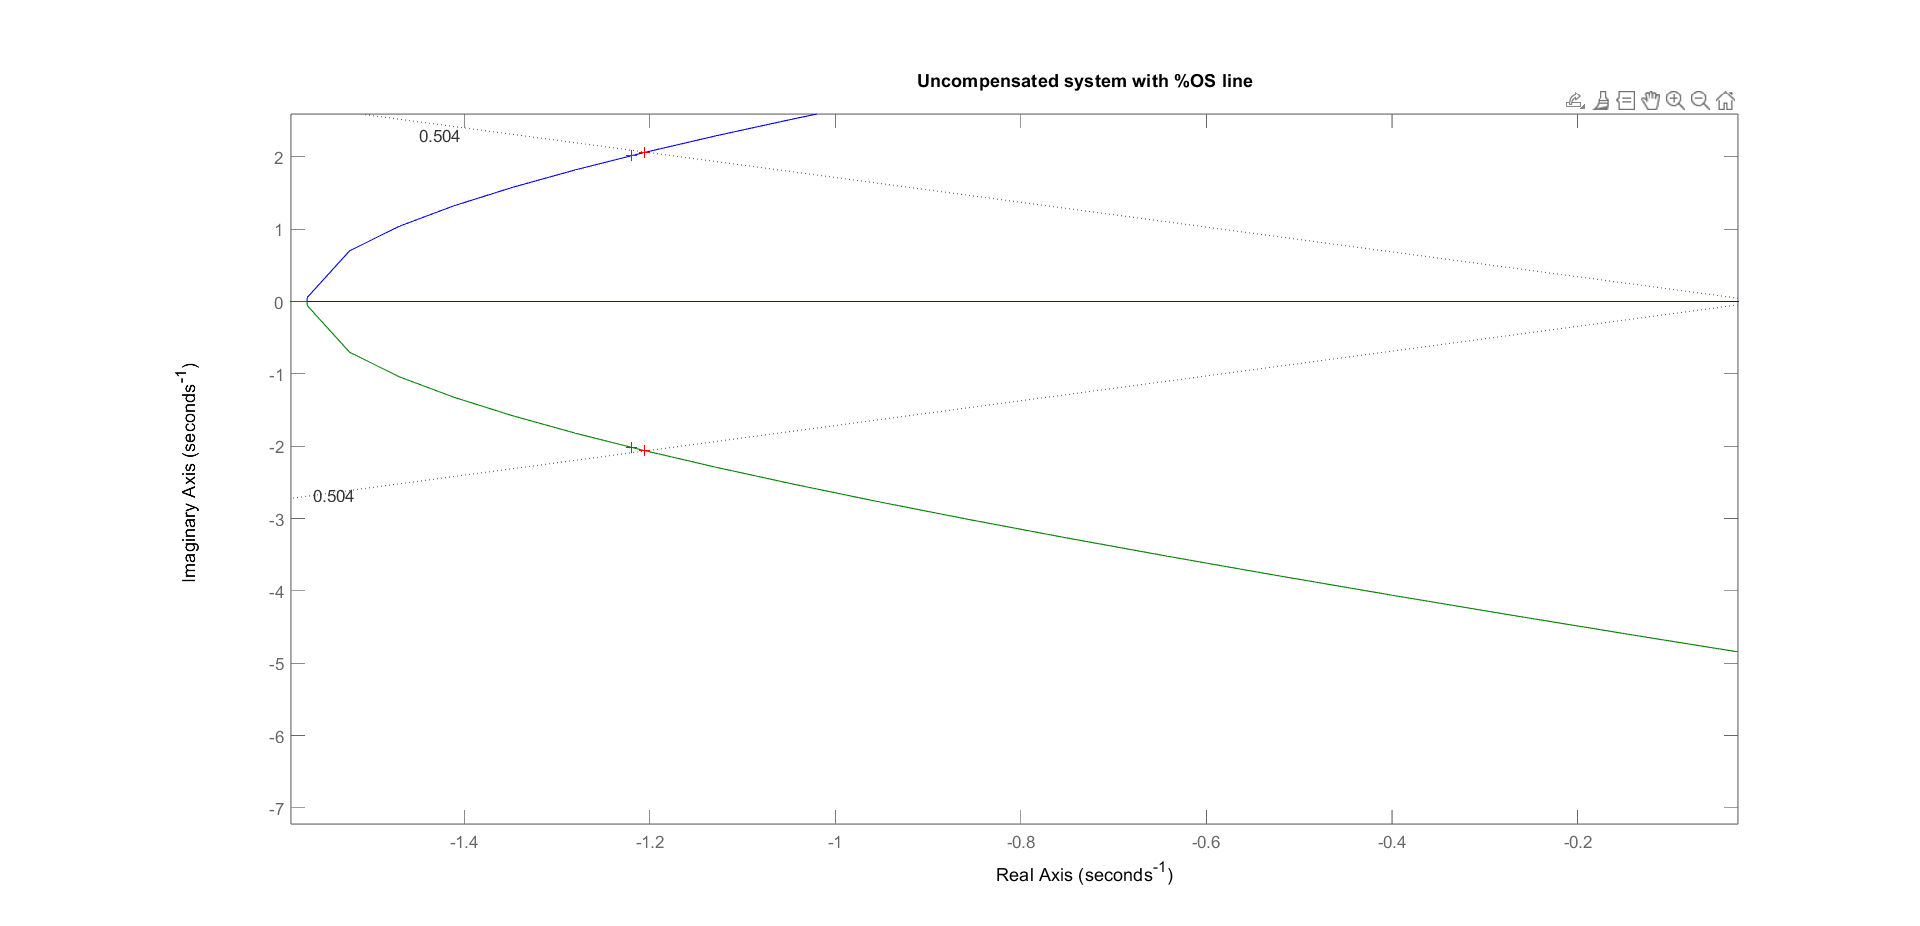

selected_point = -1.2046 + 2.0601i

[K,p] = rlocfind(G);

p

p =   -7.5884 + 0.0000i
  -1.2058 + 2.0605i
  -1.2058 - 2.0605i


f = input('Give pole number that is operating point');

operatingpoint = p(f)

operatingpoint = -1.2058 + 2.0605i

gain = K

gain = 43.2515

estimated_settling_time = 4/abs(real(p(f)))

estimated_settling_time = 3.3173

estimated_peak_time = pi/abs(imag(p(f)))

estimated_peak_time = 1.5247

estimated_pos = pos

estimated_pos = 16

estimated_damping_ratio = z

estimated_damping_ratio = 0.5039

estimated_natural_frequency = sqrt(real(p(f))^2+imag(p(f))^2)

estimated_natural_frequency = 2.3874

% Evaluating Kv
sG = tf(conv([1 0],numg),deng);
sG = minreal(sG); %to cancel common poles and zeroes
Kv = dcgain(K*sG)

Kv = 1.8021

ess = 1/Kv

ess = 0.5549

T = feedback(K*G,1)

T =
 
             43.25
  ---------------------------
  s^3 + 10 s^2 + 24 s + 43.25
 
Continuous-time transfer function.



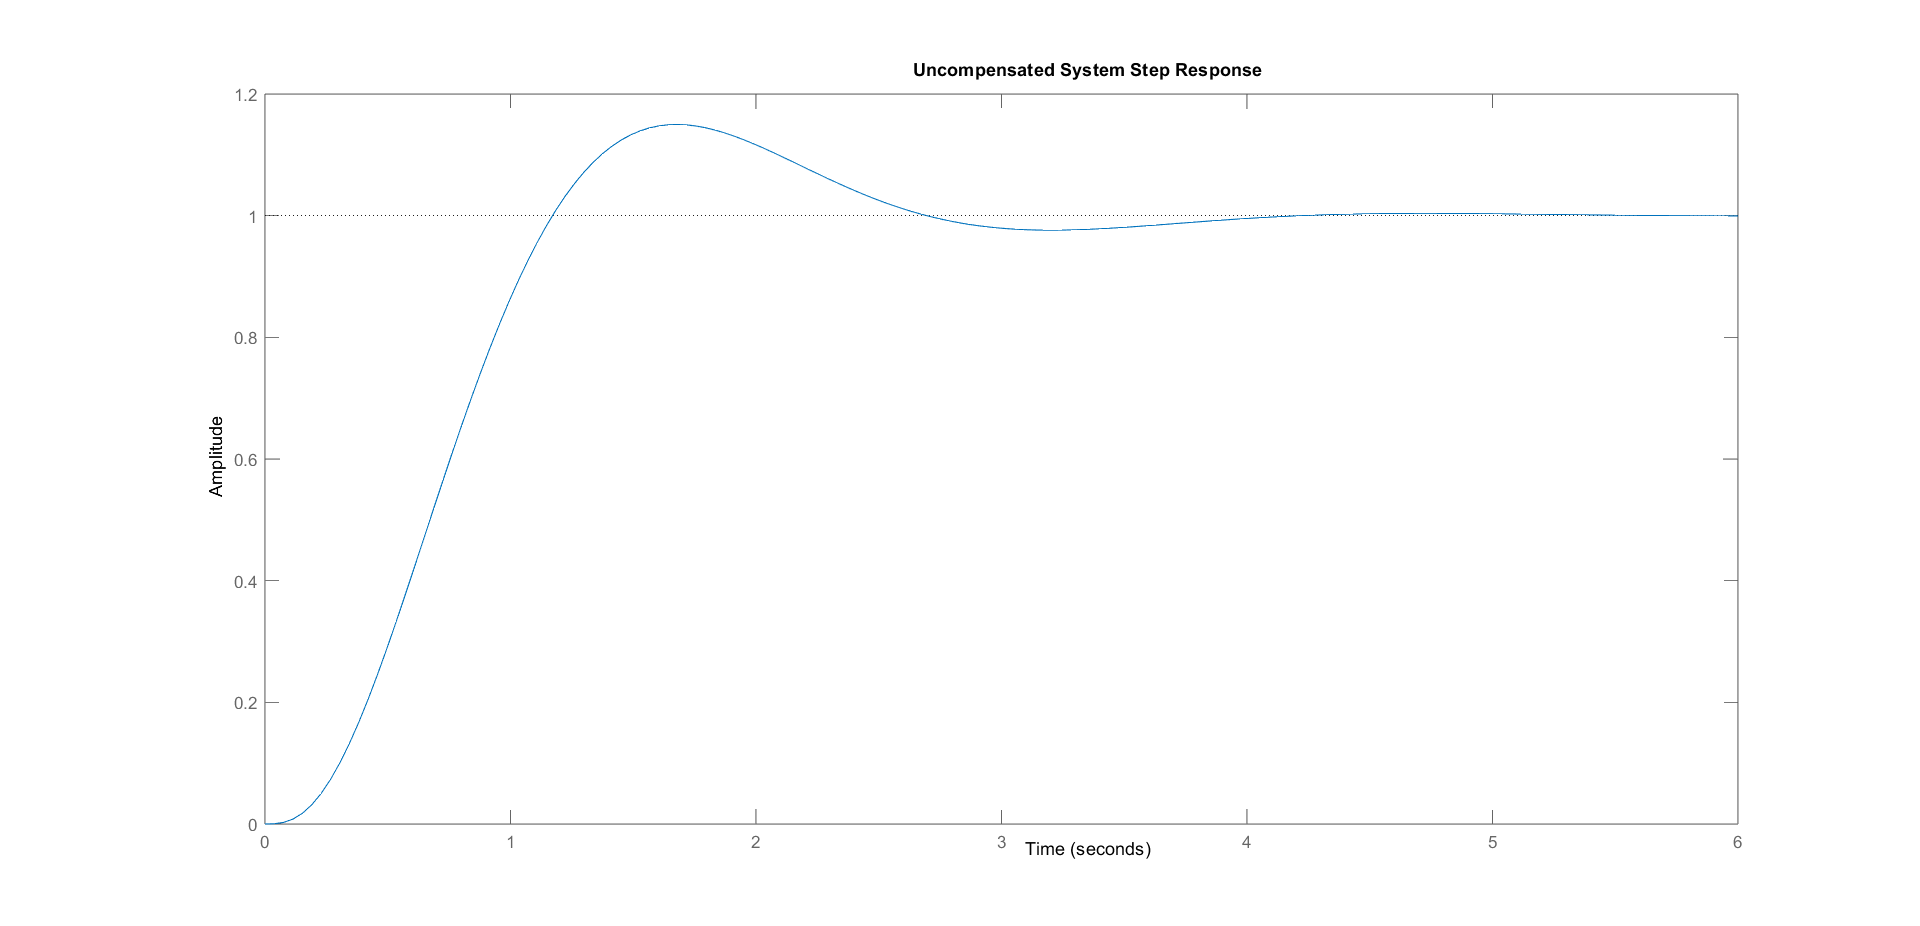

step(T)
title('Uncompensated System Step Response')

%Compensated System
Ts = input('Type Desired Settling Time')

Ts = 1.1060

wn = 4/(Ts*z)

wn = 7.1777

desired_pole = (-z*wn)+1i*(wn*sqrt(1-z^2))

desired_pole = -3.6166 + 6.2000i

angle_at_desired_pole = (180/pi)*angle(polyval(numg,desired_pole)/polyval(deng,desired_pole));
PD_angle = 180-angle_at_desired_pole

PD_angle = 95.6905

zc = imag(desired_pole)/tan(PD_angle*pi/180)-real(desired_pole)

zc = 2.9988

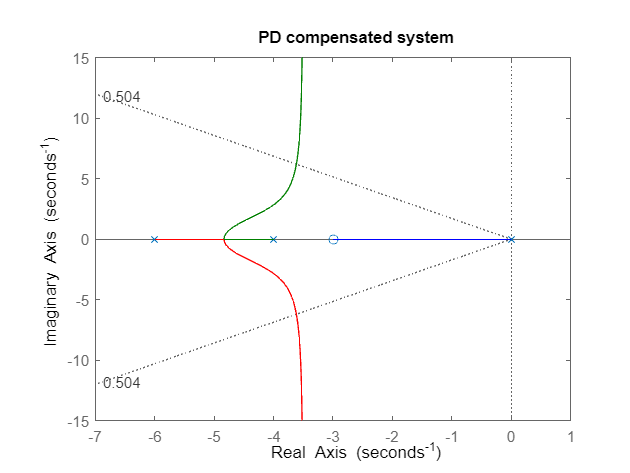

numc = [1 zc];
denc = 1;
Gc = tf(numc,denc);
Ge = G*Gc;
rlocus(Ge)
sgrid(z,0)
title('PD compensated system')

Select a point in the graphics window


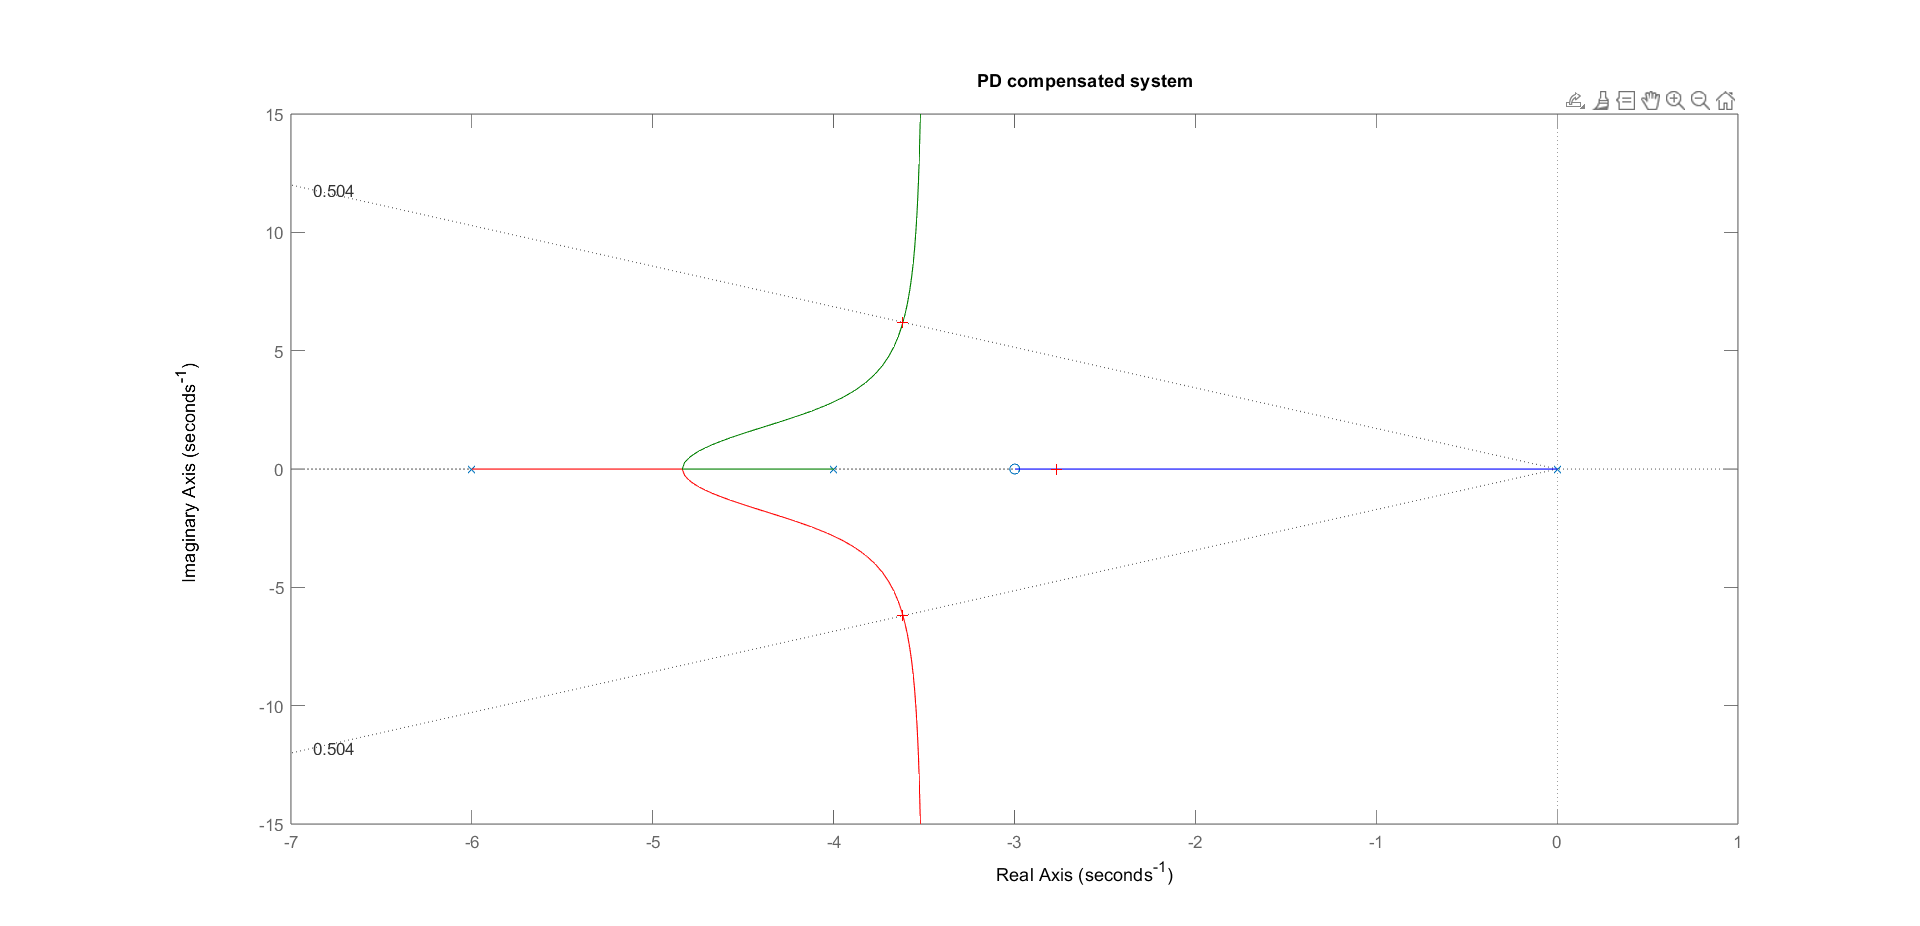

selected_point = -3.6082 + 6.1901i

[K,p] = rlocfind(Ge);

p

p =   -3.6170 + 6.1905i
  -3.6170 - 6.1905i
  -2.7660 + 0.0000i


f = input('Give pole number that is operating point');

operatingpoint = p(f)

operatingpoint = -3.6170 - 6.1905i

gain = K

gain = 47.4139

estimated_settling_time = 4/abs(real(p(f)))

estimated_settling_time = 1.1059

estimated_peak_time = pi/abs(imag(p(f)))

estimated_peak_time = 0.5075

estimated_pos = pos

estimated_pos = 16

estimated_damping_ratio = z

estimated_damping_ratio = 0.5039

estimated_natural_frequency = sqrt(real(p(f))^2+imag(p(f))^2)

estimated_natural_frequency = 7.1697

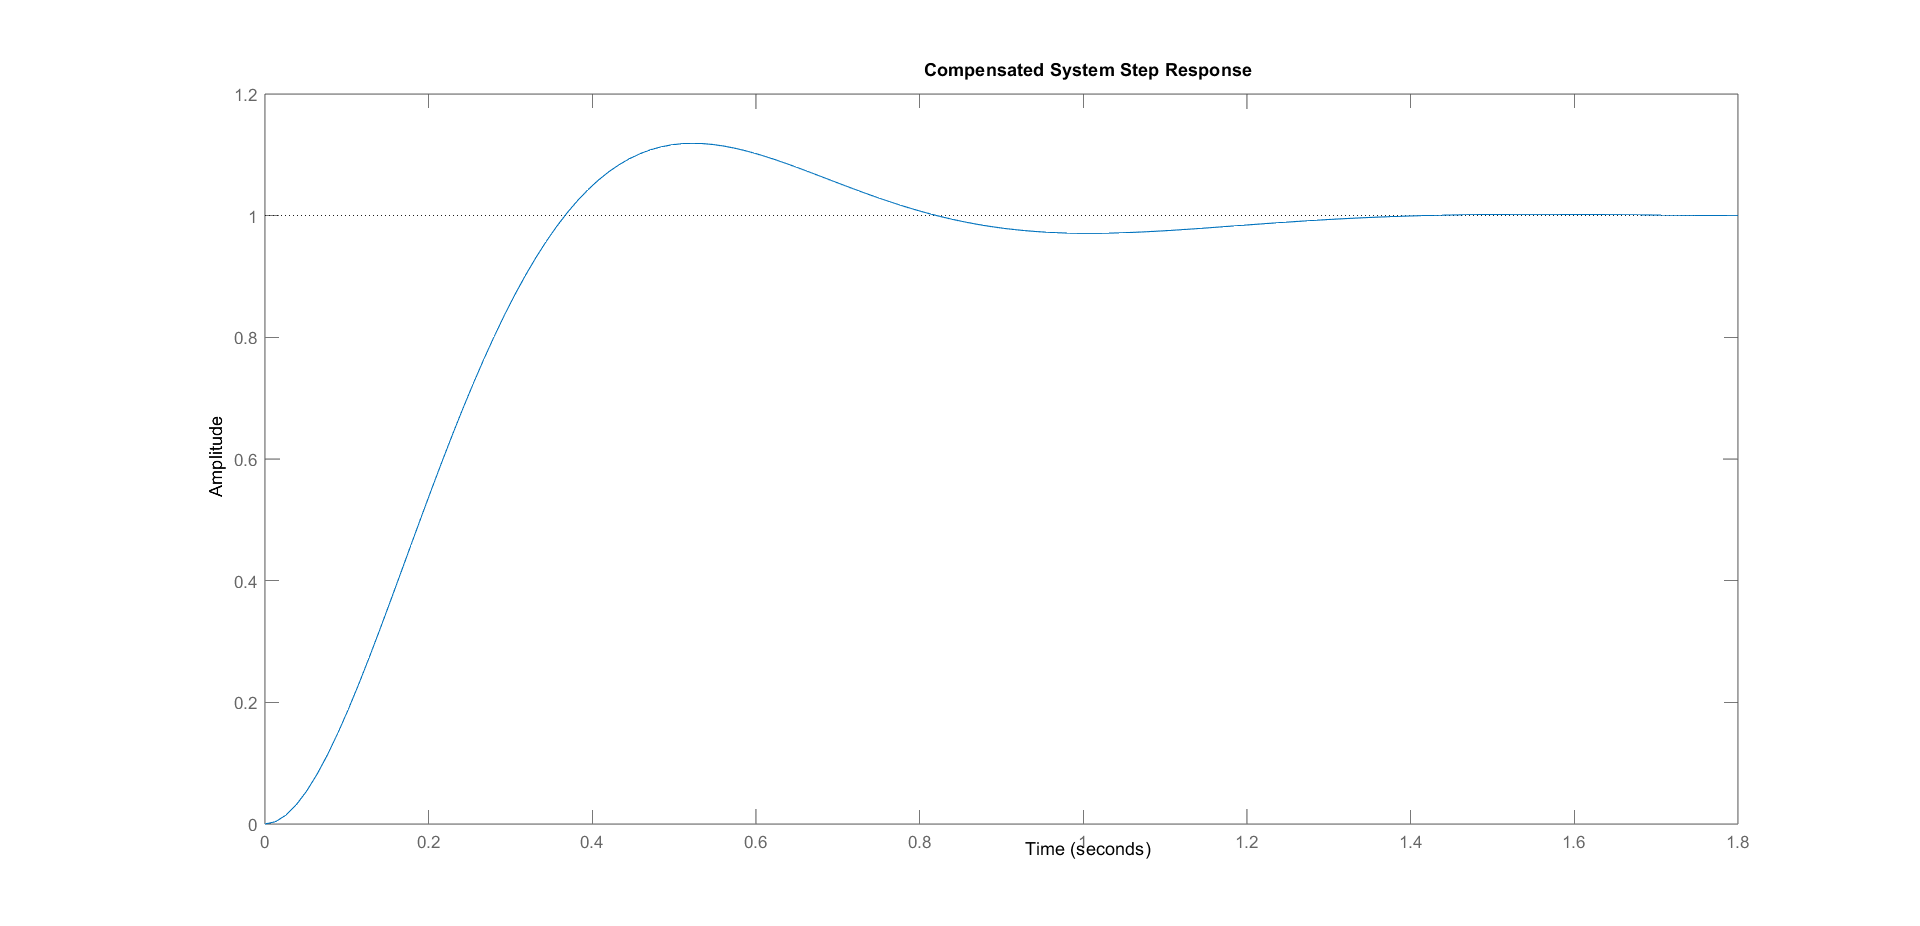

T = feedback(K*Ge,1);
step(T)
title('Compensated System Step Response')